# Training Unit 8: Arduino - MATLAB/Simulink

Fink Lucas / Teichtmeister Marcus, 05.11.2025

**Table of Contents**

## MATLAB Setup

clear
clc

Set LaTex interpreter as default for graphics

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Set font size for graphics

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Change directory (into the live script directory)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Establish Connection Between Arduino Board and MATLAB

a = arduino('COM5', 'Uno', 'BaudRate', 115200);

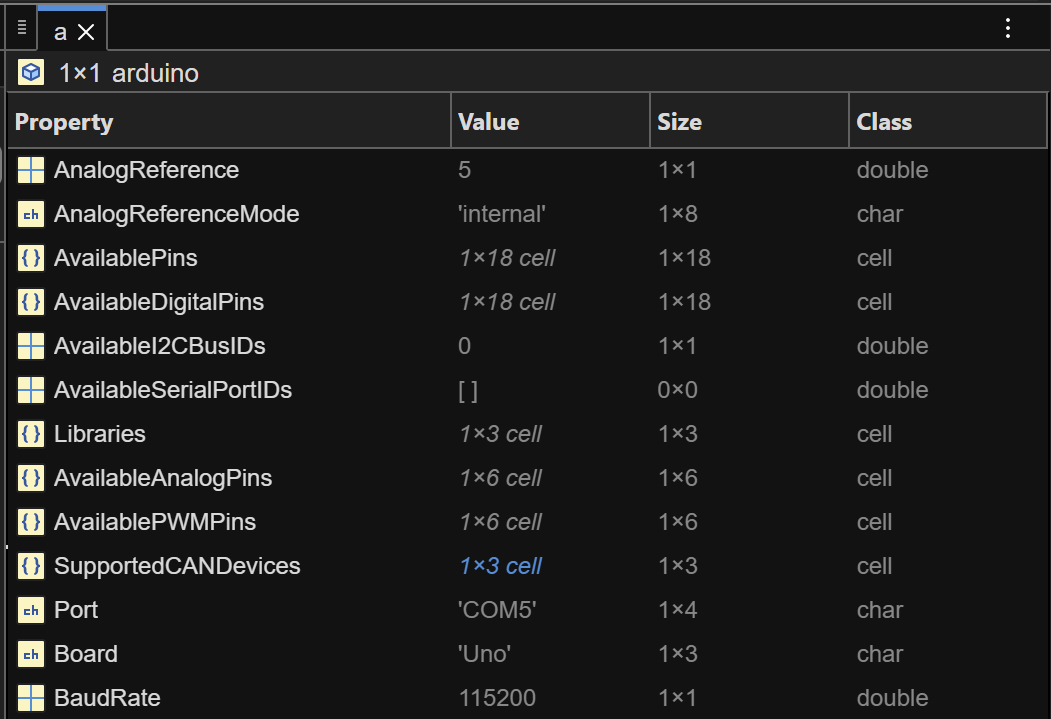

methods(a)


Methods for class arduino:

addon              apds9960           canChannel         configurePin       device             motorCarrier       playTone           readDigitalPin     readVoltage        rotaryEncoder      scanI2CBus         servo              shiftRegister      ultrasonic         writeDigitalPin    writePWMDutyCycle  writePWMVoltage    

Methods of arduino inherited from handle.



## MATLAB to Control Inputs and Outputs of Board

configurePin(a, 'D2', 'DigitalInput')

% type as DigitalInput -> input is in an undefined state (when floatend),
% there is also difference if touching the wire by hand or not
% type as Pullup -> input has an defined state (HIGH), when floatend its
% "1", gnd its "0"

ret = readDigitalPin(a, 'D2')

ret = 1

figure
plot(1,1); % create plot with dummy value
ax = gca; % get handle of current axes;
line = get(ax, 'Children') % get handle to line object

line =   Line with properties:

              Color: [0.1490 0.5490 0.8660]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 1
              YData: 1

  Show all properties


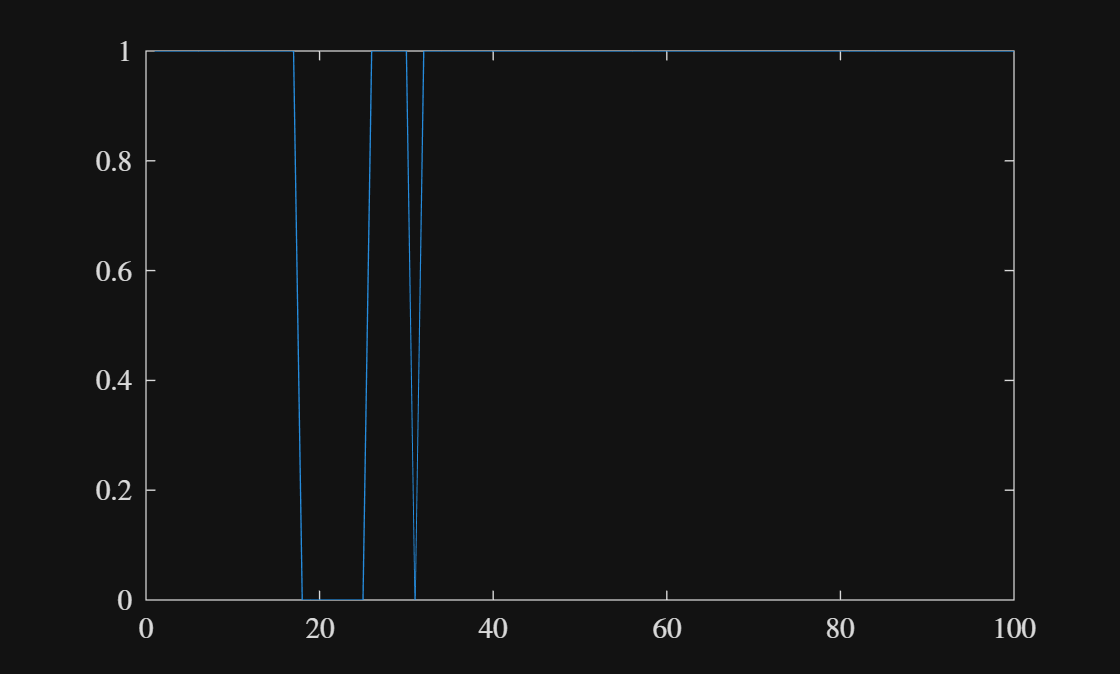

for run_var = 1 : 100
 read_value = readDigitalPin(a, 'D2');
 pause(0.1);
 line.XData = [line.XData run_var];
 line.YData = [line.YData read_value];
end

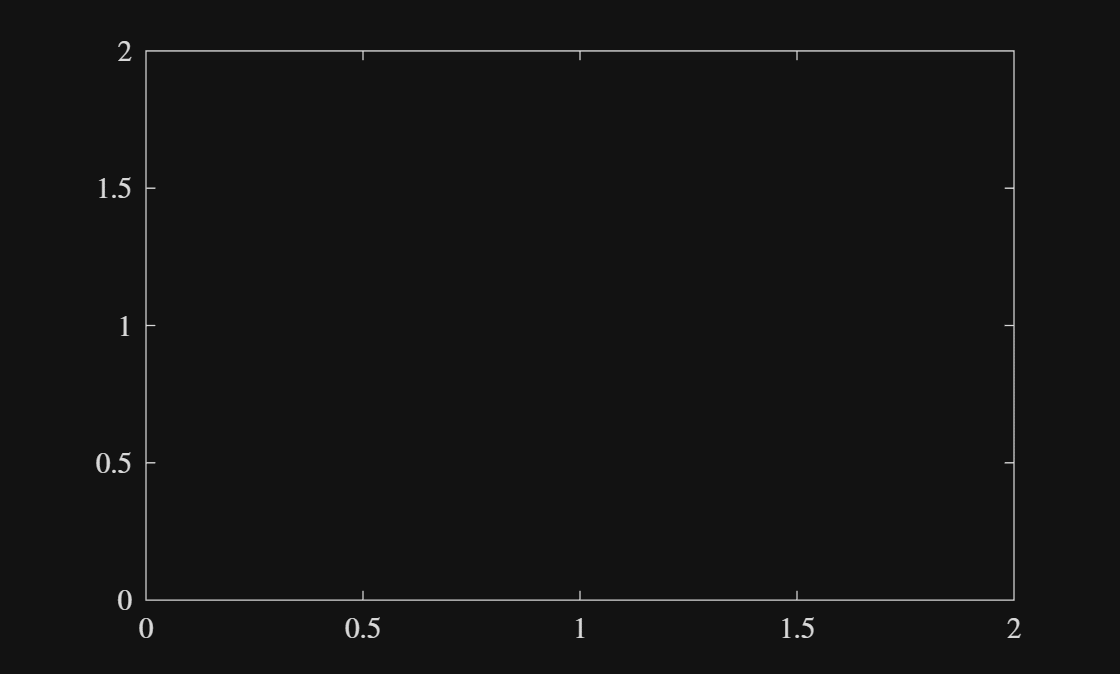

configurePin(a, 'D4', 'Pullup')
configurePin(a, 'D3', 'DigitalOutput')

writeDigitalPin(a, 'D3', 1);

readDigitalPin(a, 'D4')

ans = 1

## Minimum Cycle Time

clear
a = arduino('COM5', 'Uno', 'BaudRate', 115200);

Updating server code on board Uno (COM5). This may take a few minutes.


configurePin(a, 'D13', 'DigitalOutput')
for i = 1:100
    tic;
    writeDigitalPin(a, 'D13', 1)
    time115k(i) = toc;
    pause(0.01);
    writeDigitalPin(a, 'D13', 0)
end

clear a
a = arduino('COM5', 'Uno', 'BaudRate', 110);

Updating server code on board Uno (COM5). This may take a few minutes.


configurePin(a, 'D13', 'DigitalOutput')

for i = 1:100
    tic;
    writeDigitalPin(a, 'D13', 1)
    time110(i) = toc;
    pause(0.01);
    writeDigitalPin(a, 'D13', 0)
end

clear a
a = arduino('COM5', 'Uno', 'BaudRate', 256000);

Updating server code on board Uno (COM5). This may take a few minutes.


configurePin(a, 'D13', 'DigitalOutput')

for i = 1:100
    tic;
    writeDigitalPin(a, 'D13', 1)
    time256k(i) = toc;
    pause(0.01);
    writeDigitalPin(a, 'D13', 0)
end

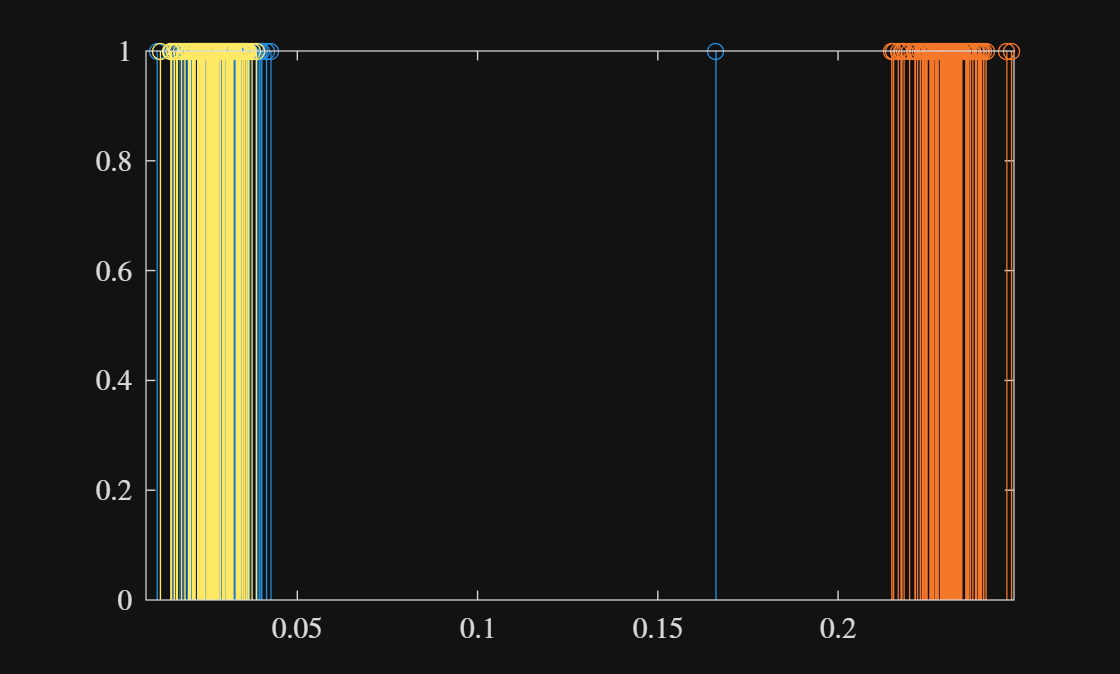


figure
clf
values = ones(1,100);
stem(time115k, values)
hold on
stem(time110, values)
stem(time256k, values)
hold off

mintime115k = min(time115k)

mintime115k = 0.0111

mintime110 = min(time110)

mintime110 = 0.2149

mintime256k = min(time256k)

mintime256k = 0.0120

configurePin(a, 'D8', 'DigitalOutput')
configurePin(a, 'D9', 'DigitalOutput')
configurePin(a, 'D10', 'DigitalOutput')
configurePin(a, 'D11', 'DigitalOutput')


    % Initialize counter variable
    counter = 0;
    
    % Loop to create a binary counter
    for i = 1:16
        % Convert counter to binary and write to output pins
        binaryValue = dec2bin(i, 4) - '0'; % Convert to binary and to numeric array
        writeDigitalPin(a, 'D8', binaryValue(1)); % Write to D8
        writeDigitalPin(a, 'D9', binaryValue(2)); % Write to D9
        writeDigitalPin(a, 'D10', binaryValue(3)); % Write to D10
        writeDigitalPin(a, 'D11', binaryValue(4)); % Write to D11
        
        % Increment counter
        pause(1); % Pause for visibility
    end


% Initialize counter variable
counter = 0;

% Loop to create a binary counter based on user input
while true
    userInput = input('Enter a number (0-15) to display in binary (leave empty to exit): ', 's');
    
    % Check if the input is numeric
    if isempty(userInput) || ~isnumeric(str2double(userInput))
        disp('Exiting the counter.');
        break; % Exit the loop if input is non-numeric
    end
    
    % Convert user input to a number
    numValue = str2double(userInput);
    
    % Validate the input range
    if numValue >= 0 && numValue <= 15
        % Convert counter to binary and write to output pins
        binaryValue = dec2bin(numValue, 4) - '0'; % Convert to binary and to numeric array
        writeDigitalPin(a, 'D8', binaryValue(1)); % Write to D8
        writeDigitalPin(a, 'D9', binaryValue(2)); % Write to D9
        writeDigitalPin(a, 'D10', binaryValue(3)); % Write to D10
        writeDigitalPin(a, 'D11', binaryValue(4)); % Write to D11
    else
        disp('Please enter a number between 0 and 15.');
    end
end

Please enter a number between 0 and 15.
Please enter a number between 0 and 15.
Please enter a number between 0 and 15.


Exiting the counter.


## PWM

configurePin(a, 'D5', 'PWM')

writePWMVoltage(a, 'D5', 2)

for i = 1:5
    writePWMVoltage(a, 'D5', i)
    pause(1)
end
for k = 1:5
    writePWMVoltage(a, 'D5', 5-k)
    pause(1)
end

configurePin(a, 'A0', 'AnalogInput')

readVoltage(a, 'A0')

ans = 5

% when connecting to output (PWM), it reads the wrong voltage (due to high
% resistance of led)

readVoltage(a, 'A0')

ans = 5

writePWMVoltage(a, 'D5', readVoltage(a,'A0'))
% dont know if poti works correctly (small range where voltage changes)